导入网格

% addpath('.\import')
% [Nnode, Nelement, Coordinate, Ielement] = read_mesh_info("mesh_simple.dat");

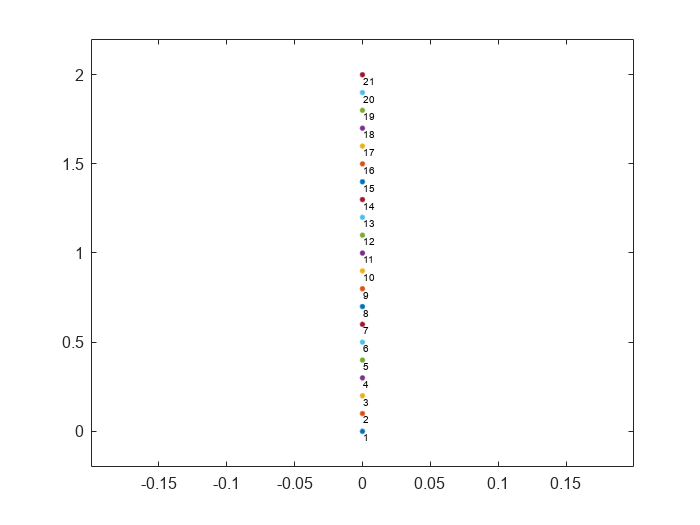

% iNode = 1:Nnode; % 绘制的节点编号
iNode = n.left; % 左边界节点
% iNode = n.right; % 右边界节点

t = 2e-1; % 动画帧时间

figure()
for ii = 1:length(iNode)
	i = iNode(ii);
	plot(Coordinate(i,1),Coordinate(i,2),'.','MarkerSize',10)
	xlim([min(Coordinate(iNode,1)-dL),max(Coordinate(iNode,1))+dL])
	ylim([min(Coordinate(iNode,2)-dW),max(Coordinate(iNode,2))+dW])
	text(Coordinate(i,1),Coordinate(i,2),num2str(i),'FontSize',6,'VerticalAlignment','top','HorizontalAlignment','left')
	pause(t)
	hold on
end
% axis padded
hold off

%{
% iElement = 1:10; % 绘制的单元编号
iElement = eRight; % 右边界单元

函数或变量 'eRight' 无法识别。

% iElement = eLeft; % 左边界单元

t = 0.01; % 动画帧时间

figure()

nodes = Ielement(iElement,:);
plot(nan,nan)
hold on
xlim([min(Coordinate(nodes(:),1)-dL/b),max(Coordinate(nodes(:),1))+dL/b]);
ylim([min(Coordinate(nodes(:),2)-dW/b),max(Coordinate(nodes(:),2))+dW/b]);

for i = 1:length(iElement)
	draw(iElement(i),t,Ielement,Coordinate)
end
hold off
%}

function draw(iElement,t,Ielement,Coordinate)
% global Ielement Coordinate
ele1 = Ielement(iElement,:);
for i = 1:length(ele1)
	plot(Coordinate(ele1(i),1),Coordinate(ele1(i),2),'.','MarkerSize',10)
	% 	xlim([min(Coordinate(ele1(:),1)),max(Coordinate(ele1(:),1))])
	% 	ylim([min(Coordinate(ele1(:),2)),max(Coordinate(ele1(:),2))])
	text(Coordinate(ele1(i),1),Coordinate(ele1(i),2),num2str(ele1(i)))
	pause(t)
end
end